clear all
close all
L=[2.5 1 1.5 2.5];
Q=[0.5 1 0.5];
[M01_ M1_1 M12 M23]=PositionMat(Q,L)

M01_ =     1.0000         0         0    2.1940
         0    1.0000         0         0
         0         0    1.0000   -1.1986
         0         0         0    1.0000


M1_1 =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


M12 =     0.7702   -0.5950    0.2298    1.1552
    0.5950    0.5403   -0.5950    0.8925
    0.2298    0.5950    0.7702    0.3448
         0         0         0    1.0000


M23 =     0.8776         0    0.4794    2.1940
         0    1.0000         0         0
   -0.4794         0    0.8776   -1.1986
         0         0         0    1.0000


M01=M01_*M1_1

M01 =     1.0000         0         0    3.1940
         0    1.0000         0         0
         0         0    1.0000   -1.1986
         0         0         0    1.0000


M02=M01*M12

M02 =     0.7702   -0.5950    0.2298    4.3492
    0.5950    0.5403   -0.5950    0.8925
    0.2298    0.5950    0.7702   -0.8538
         0         0         0    1.0000


M03=M02*M23

M03 =     0.5657   -0.5950    0.5709    5.7634
    0.8074    0.5403   -0.2369    2.9111
   -0.1675    0.5950    0.7861   -1.2726
         0         0         0    1.0000


M03*[0 0 0 1]'

ans =     5.7634
    2.9111
   -1.2726
    1.0000


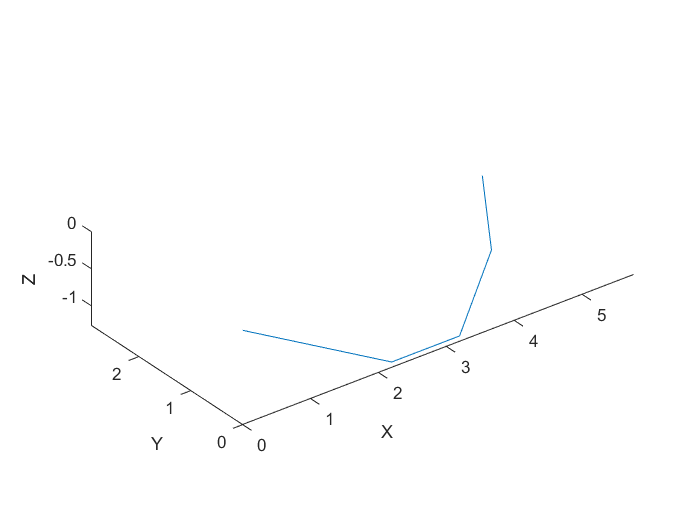

plotRobot(Q,L,1)